% Solar Energy Data Analysis & Decision-Making
clc; clear; close all;

%% a) Data Preprocessing
% Load dataset
filename = 'Refined_Solar_Energy_Data.xlsx';
data = readtable(filename);

% Display initial structure
disp('Initial Data Preview:');

Initial Data Preview:


disp(head(data));

       Date        Month         PanelType         SolarRadiation_Wm2    Efficiency    EnergyOutput_kWh    TotalCost
    ___________    _____    ___________________    __________________    __________    ________________    _________

    01-Jan-2024      1      {'Thin-Film'      }          167.08            0.1285           0.824            0.058  
    02-Jan-2024      1      {'Monocrystalline'}          167.08            0.1749           1.122            0.112  
    03-Jan-2024      1      {'Thin-Film'      }          167.08            0.1308           0.839            0.059  
    04-Jan-2024      1      {'Thin-Film'      }          167.08            0.1495           0.959            0.067  
    05-Jan-2024      1      {'Monocrystalline'}          16


% Handle missing values
data = rmmissing(data);

% Extract relevant features
% Assuming columns are: Date, PanelType, EnergyOutput_kWh, SolarRadiation_Wm2, TotalCost
data.Date = datetime(data.Date, 'InputFormat', 'yyyy-MM-dd'); % Adjust as needed
data.Month = month(data.Date);

%% b) Performance Analysis
% Compute efficiency for each record
data.Efficiency = data.EnergyOutput_kWh ./ data.SolarRadiation_Wm2;

% Average performance by panel type over time
panelTypes = unique(data.PanelType);
avgEfficiency = zeros(length(panelTypes), 1);

for i = 1:length(panelTypes)
    panelData = data(strcmp(data.PanelType, panelTypes{i}), :);
    avgEfficiency(i) = mean(panelData.Efficiency);
end

% Display average efficiencies
efficiencyTable = table(panelTypes, avgEfficiency, 'VariableNames', {'PanelType', 'AvgEfficiency'});
disp('Average Efficiency by Panel Type:');

Average Efficiency by Panel Type:


disp(efficiencyTable);

         PanelType         AvgEfficiency
    ___________________    _____________

    {'Monocrystalline'}      0.0074775  
    {'Polycrystalline'}      0.0057284  
    {'Thin-Film'      }       0.004869  




%% c) Decision-Making Criteria
% Compute cost per kWh
data.CostPerkWh = data.TotalCost ./ data.EnergyOutput_kWh;

% Aggregate performance metrics by panel type
summaryStats = groupsummary(data, 'PanelType', {'mean'}, {'EnergyOutput_kWh', 'Efficiency', 'CostPerkWh'});

% Rename columns for clarity
summaryStats.Properties.VariableNames = {'PanelType', 'GroupCount', 'AvgEnergyOutput', 'AvgEfficiency', 'AvgCostPerkWh'};
disp('Summary Stats by Panel Type:');

Summary Stats by Panel Type:


disp(summaryStats);

         PanelType         GroupCount    AvgEnergyOutput    AvgEfficiency    AvgCostPerkWh
    ___________________    __________    _______________    _____________    _____________

    {'Monocrystalline'}       126            1.9951           0.0074775         0.10002   
    {'Polycrystalline'}       112            1.5528           0.0057284        0.079983   
    {'Thin-Film'      }       127            1.2924            0.004869        0.070034   



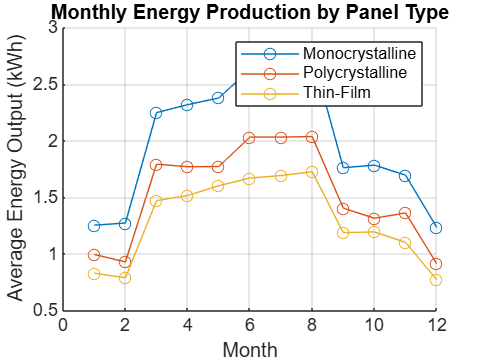


%% d) Visualization & Reporting

% Plot energy production trend over months
figure;
hold on;
for i = 1:length(panelTypes)
    panelData = data(strcmp(data.PanelType, panelTypes{i}), :);
    monthlyAvg = groupsummary(panelData, 'Month', 'mean', 'EnergyOutput_kWh');
    plot(monthlyAvg.Month, monthlyAvg.mean_EnergyOutput_kWh, '-o', 'DisplayName', panelTypes{i});
end
hold off;
xlabel('Month');
ylabel('Average Energy Output (kWh)');
title('Monthly Energy Production by Panel Type');
legend;
grid on;

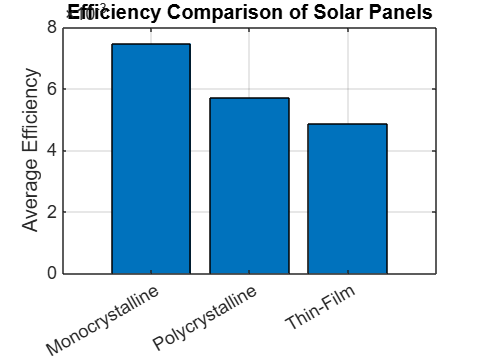


% Bar chart comparing average efficiency
figure;
bar(categorical(summaryStats.PanelType), summaryStats.AvgEfficiency);
ylabel('Average Efficiency');
title('Efficiency Comparison of Solar Panels');
grid on;

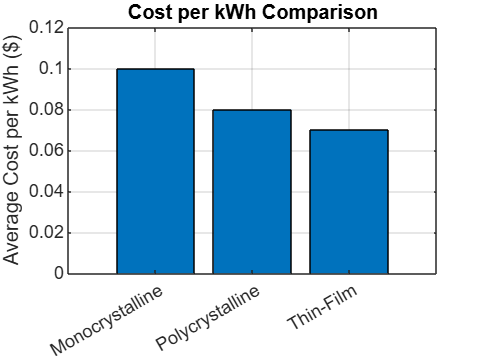


% Bar chart comparing cost per kWh
figure;
bar(categorical(summaryStats.PanelType), summaryStats.AvgCostPerkWh);
ylabel('Average Cost per kWh ($)');
title('Cost per kWh Comparison');
grid on;


%% Summary Recommendation
[~, bestPanelIdx] = max(summaryStats.AvgEfficiency ./ summaryStats.AvgCostPerkWh);
bestPanel = summaryStats.PanelType{bestPanelIdx};
fprintf('\nRecommended Panel Type: %s (Best Efficiency-to-Cost Ratio)\n', bestPanel);


Recommended Panel Type: Monocrystalline (Best Efficiency-to-Cost Ratio)
